# Termico - taller1 corte2

Asignacion de Polos

clear all
clc

%%Matrices
A = [-1 1; 
    0.5 -1.5]

A =    -1.0000    1.0000
    0.5000   -1.5000


B = [0.5; 0]

B =     0.5000
         0


C = [1 0]

C =      1     0


D = 0

D = 0

[num,den] = ss2tf(A,B,C,D) 

num =          0    0.5000    0.7500


den =     1.0000    2.5000    1.0000


TF=tf(num,den)

TF =
 
   0.5 s + 0.75
  ---------------
  s^2 + 2.5 s + 1
 
Continuous-time transfer function.
Model Properties


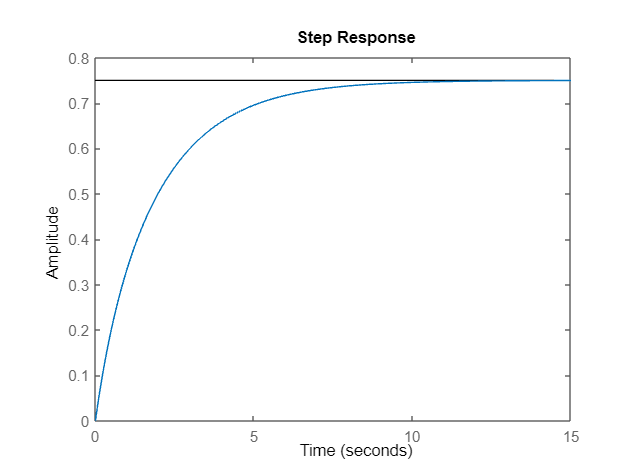

step(TF)

Ts = 1;
Gd = c2d(TF,Ts,'zoh')

Gd =
 
     0.3344 z - 0.0792
  ------------------------
  z^2 - 0.7419 z + 0.08208
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


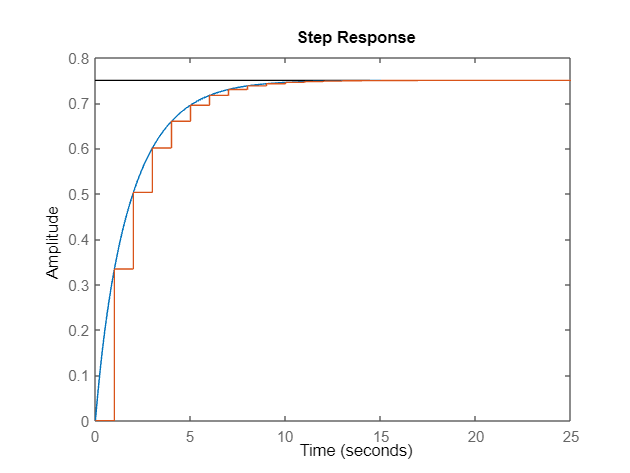

step(TF,Gd)

syms s k1 k2 ki
k=[k1 k2]

$$k = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

sI = s*eye(3)

$$sI = \left(\begin{array}{ccc} s & 0 & 0\\ 0 & s & 0\\ 0 & 0 & s \end{array}\right)$$

Bk= B*[k1 k2]

$$Bk = \left(\begin{array}{cc} \frac{k_{1}}{2} & \frac{k_{2}}{2}\\ 0 & 0 \end{array}\right)$$

A_Bk = A-Bk

$$A\_Bk = \left(\begin{array}{cc} -\frac{k_{1}}{2}-1 & 1-\frac{k_{2}}{2}\\ \frac{1}{2} & -\frac{3}{2} \end{array}\right)$$

B_ki= B*[ki]

$$B\_ki = \left(\begin{array}{c} \frac{\mathrm{ki}}{2}\\ 0 \end{array}\right)$$


A_asq=[A-Bk B_ki;
    -C 0]

$$A\_asq = \left(\begin{array}{ccc} -\frac{k_{1}}{2}-1 & 1-\frac{k_{2}}{2} & \frac{\mathrm{ki}}{2}\\ \frac{1}{2} & -\frac{3}{2} & 0\\ -1 & 0 & 0 \end{array}\right)$$


sI_A_Bk = sI-A_asq

$$sI\_A\_Bk = \left(\begin{array}{ccc} \frac{k_{1}}{2}+s+1 & \frac{k_{2}}{2}-1 & -\frac{\mathrm{ki}}{2}\\ -\frac{1}{2} & s+\frac{3}{2} & 0\\ 1 & 0 & s \end{array}\right)$$

PC_0 = det(sI_A_Bk)

$$PC\_0 = \frac{3\,\mathrm{ki}}{4}+s+\frac{3\,k_{1}\,s}{4}+\frac{k_{2}\,s}{4}+\frac{\mathrm{ki}\,s}{2}+\frac{k_{1}\,s^{2}}{2}+\frac{5\,s^{2}}{2}+s^{3}$$

PC=vpa(fliplr(coeffs(PC_0,s)),3)

$$PC = \left(\begin{array}{cccc} 1.0 & 0.5\,k_{1}+2.5 & 0.75\,k_{1}+0.25\,k_{2}+0.5\,\mathrm{ki}+1.0 & 0.75\,\mathrm{ki} \end{array}\right)$$

zeta = 0.7

zeta = 0.7000

ts = 10

ts = 10

wn = 4/(ts*zeta)

wn = 0.5714

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)

$$PD\_0 = \left(s+4\right)\,\left(s^{2}+\frac{4\,s}{5}+\frac{16}{49}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{cccc} 1.0 & 4.8 & 3.53 & 1.31 \end{array}\right)$$

f0=vpa(PC(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PC(2)==PD(2),3)

$$f1 = 0.5\,k_{1}+2.5=4.8$$

f2=vpa(PC(3)==PD(3),3)

$$f2 = 0.75\,k_{1}+0.25\,k_{2}+0.5\,\mathrm{ki}+1.0=3.53$$

f3=vpa(PC(4)==PD(4),3)

$$f3 = 0.75\,\mathrm{ki}=1.31$$

solucion=solve(f1,f2,f3)

solucion = struct with fields:
    k1: 4.6000000000931322574615478515625
    k2: -7.1768707485559086004892985026042
    ki: 1.7414965986584623654683430989583


k1 = double(round(solucion.k1,3))

k1 = 4.6000

k2 = double(round(solucion.k2,3))

k2 = -7.1770

ki = double(round(solucion.ki,3))

ki = 1.7410

Matriz Transformacion con accion integral

disp('Matriz de Transformacion')

Matriz de Transformacion


A_t = [-1 1 0; 
    0.5 -1.75 0; 
    -1 0 0]

A_t =    -1.0000    1.0000         0
    0.5000   -1.7500         0
   -1.0000         0         0


B_t = [0.5; 0; 0]

B_t =     0.5000
         0
         0


C_t = [1 0 0]

C_t =      1     0     0


D = 0

D = 0

sI_t = s*eye(3)

$$sI\_t = \left(\begin{array}{ccc} s & 0 & 0\\ 0 & s & 0\\ 0 & 0 & s \end{array}\right)$$

sI_t_At = sI_t-A_t

$$sI\_t\_At = \left(\begin{array}{ccc} s+1 & -1 & 0\\ -\frac{1}{2} & s+\frac{7}{4} & 0\\ 1 & 0 & s \end{array}\right)$$

PC_t0 = det(sI_t_At)

$$PC\_t0 = s^{3}+\frac{11\,s^{2}}{4}+\frac{5\,s}{4}$$

PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{ccc} 1.0 & 2.75 & 1.25 \end{array}\right)$$

Con_t = [B_t A_t*B_t (A_t)^2*B_t]

Con_t =     0.5000   -0.5000    0.7500
         0    0.2500   -0.6875
         0   -0.5000    0.5000


syms a1 a2
a1 = 2.75

a1 = 2.7500

a2 = 1.25

a2 = 1.2500

M_t = [a2 a1 1;
    a1 1 0;
    1 0 0]

M_t =     1.2500    2.7500    1.0000
    2.7500    1.0000         0
    1.0000         0         0


T_t = Con_t*M_t

T_t =          0    0.8750    0.5000
         0    0.2500         0
   -0.8750   -0.5000         0


T_t_inv = inv(T_t)

T_t_inv =          0   -2.2857   -1.1429
         0    4.0000         0
    2.0000   -7.0000         0


%%%%%%%%%%
PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{ccc} 1.0 & 2.75 & 1.25 \end{array}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)          

$$PD = \left(\begin{array}{cccc} 1.0 & 4.8 & 3.53 & 1.31 \end{array}\right)$$


K_t = [1.31-0 3.53-1.25 4.8-2.75]*T_t_inv  %% CAMBIA

K_t =     4.1000   -8.2243   -1.4971


Ackerman

%% Se reemplaza en el deseado
MI = [1 0 0;
      0 1 0;
      0 0 1]

MI =      1     0     0
     0     1     0
     0     0     1


phi_A = (A_t^3)+(4.8*A_t^2)+(3.53*A_t)+(1.31*MI) %% CAMBIA

phi_A =     2.1050   -3.3575         0
   -1.6787    4.6231         0
   -0.2300   -2.0500    1.3100


 K_ack = [0 0 1]*(inv(Con_t))*phi_A

K_ack =     4.1000   -8.2243   -1.4971


Ganancias

 %% Asignacion de Polos
 K_polos = [k1 k2 ki]

K_polos =     4.6000   -7.1770    1.7410


 %% Matriz T
 K_t

K_t =     4.1000   -8.2243   -1.4971


 %% Ackerman
 K_ack

K_ack =     4.1000   -8.2243   -1.4971


**2) Observador**

%%Observador
syms L1 L2
L=[L1;L2]

$$L = \left(\begin{array}{c} L_{1}\\ L_{2} \end{array}\right)$$

A_LC= A-(L*C)

$$A\_LC = \left(\begin{array}{cc} -L_{1}-1 & 1\\ \frac{1}{2}-L_{2} & -\frac{3}{2} \end{array}\right)$$

sI_obs = s*eye(2)

$$sI\_obs = \left(\begin{array}{cc} s & 0\\ 0 & s \end{array}\right)$$

disp('Calculos del Observador')

Calculos del Observador


PL_0=vpa(det(sI_obs-A_LC),3)

$$PL\_0 = 1.5\,L_{1}+L_{2}+2.5\,s+L_{1}\,s+s^{2}+1.0$$

PL_1 = collect(expand(det(s*eye(2)-A_LC)),s)

$$PL\_1 = s^{2}+\left(L_{1}+\frac{5}{2}\right)\,s+\frac{3\,L_{1}}{2}+L_{2}+1$$

PL=vpa(fliplr(coeffs(PL_0,s)),3)

$$PL = \left(\begin{array}{ccc} 1.0 & L_{1}+2.5 & 1.5\,L_{1}+L_{2}+1.0 \end{array}\right)$$

zeta = 0.7

zeta = 0.7000

ts = 10/10 %% Debe ser mas rapido que el sistema controlado

ts = 1

wn = 4/(ts*zeta)

wn = 5.7143

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)

$$PD\_0 = s^{2}+8\,s+\frac{1600}{49}$$

PD=fliplr(coeffs(PD_0,s))

$$PD = \left(\begin{array}{ccc} 1 & 8 & \frac{1600}{49} \end{array}\right)$$

f0=vpa(PL(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PL(2)==PD(2),3)

$$f1 = L_{1}+2.5=8.0$$

f2=vpa(PL(3)==PD(3),3)

$$f2 = 1.5\,L_{1}+L_{2}+1.0=32.7$$

solucion=solve(f1,f2)

solucion = struct with fields:
    L1: 5.5
    L2: 23.40306122414767742156982421875


L1 = double(round(solucion.L1,3))

L1 = 5.5000

L2 = double(round(solucion.L2,3))

L2 = 23.4030

**OBSERVADOR ACKERMAN**

Con_obs_po = [C;C*A]

Con_obs_po =      1     0
    -1     1


Mi_obs = [1 0;0 1]

Mi_obs =      1     0
     0     1


phi_A_obs = (A^2)+(8*A)+(32.7*Mi_obs)

phi_A_obs =    26.2000    5.5000
    2.7500   23.4500


L_obs_Ack = phi_A_obs*inv(Con_obs_po)*[0;1]

L_obs_Ack =     5.5000
   23.4500


**OBSERVADOR MATRIZ T**

PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{ccc} 1.0 & 2.75 & 1.25 \end{array}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccc} 1.0 & 8.0 & 32.7 \end{array}\right)$$

a1 =2.75

a1 = 2.7500

a2 =1.25

a2 = 1.2500

W_obs=[a1 1;
    1 0]

W_obs =     2.7500    1.0000
    1.0000         0


T_t = W_obs*Con_obs_po

T_t =     1.7500    1.0000
    1.0000         0


T_t_inv = inv(T_t)

T_t_inv =          0    1.0000
    1.0000   -1.7500


L_t = T_t_inv*[32.7-1.25;8-2.75]

L_t =     5.2500
   22.2625


Ganancias del observador

L_polos = [L1 L2]

L_polos =     5.5000   23.4030


L_obs_Ack

L_obs_Ack =     5.5000
   23.4500


L_t

L_t =     5.2500
   22.2625


**CONTROL PARA RAMPA**

Asignacion de Polos

syms s k1 k2 ki ki2
k=[k1 k2]

$$k = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

sI = s*eye(4)

$$sI = \left(\begin{array}{cccc} s & 0 & 0 & 0\\ 0 & s & 0 & 0\\ 0 & 0 & s & 0\\ 0 & 0 & 0 & s \end{array}\right)$$

Bk= B*[k1 k2]

$$Bk = \left(\begin{array}{cc} \frac{k_{1}}{2} & \frac{k_{2}}{2}\\ 0 & 0 \end{array}\right)$$

A_Bk = A-Bk

$$A\_Bk = \left(\begin{array}{cc} -\frac{k_{1}}{2}-1 & 1-\frac{k_{2}}{2}\\ \frac{1}{2} & -\frac{3}{2} \end{array}\right)$$

B_ki= B*[ki ki2]

$$B\_ki = \left(\begin{array}{cc} \frac{\mathrm{ki}}{2} & \frac{{\mathrm{ki}}_{2}}{2}\\ 0 & 0 \end{array}\right)$$


A_asq=[A-Bk B_ki;
    -C 0 0;
     0 0 1 0]

$$A\_asq = \left(\begin{array}{cccc} -\frac{k_{1}}{2}-1 & 1-\frac{k_{2}}{2} & \frac{\mathrm{ki}}{2} & \frac{{\mathrm{ki}}_{2}}{2}\\ \frac{1}{2} & -\frac{3}{2} & 0 & 0\\ -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$


sI_A_Bk = sI-A_asq

$$sI\_A\_Bk = \left(\begin{array}{cccc} \frac{k_{1}}{2}+s+1 & \frac{k_{2}}{2}-1 & -\frac{\mathrm{ki}}{2} & -\frac{{\mathrm{ki}}_{2}}{2}\\ -\frac{1}{2} & s+\frac{3}{2} & 0 & 0\\ 1 & 0 & s & 0\\ 0 & 0 & -1 & s \end{array}\right)$$

PC_0 = det(sI_A_Bk)

$$PC\_0 = \frac{3\,{\mathrm{ki}}_{2}}{4}+\frac{3\,\mathrm{ki}\,s}{4}+\frac{{\mathrm{ki}}_{2}\,s}{2}+\frac{3\,k_{1}\,s^{2}}{4}+\frac{k_{1}\,s^{3}}{2}+\frac{k_{2}\,s^{2}}{4}+\frac{\mathrm{ki}\,s^{2}}{2}+s^{2}+\frac{5\,s^{3}}{2}+s^{4}$$

PC=vpa(fliplr(coeffs(PC_0,s)),3)

$$PC = \left(\begin{array}{ccccc} 1.0 & 0.5\,k_{1}+2.5 & 0.75\,k_{1}+0.25\,k_{2}+0.5\,\mathrm{ki}+1.0 & 0.75\,\mathrm{ki}+0.5\,{\mathrm{ki}}_{2} & 0.75\,{\mathrm{ki}}_{2} \end{array}\right)$$

zeta = 0.7

zeta = 0.7000

ts = 10

ts = 10

wn = 4/(ts*zeta)

wn = 0.5714

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)*(s+betha*zeta*wn)

$$PD\_0 = {\left(s+4\right)}^{2}\,\left(s^{2}+\frac{4\,s}{5}+\frac{16}{49}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 8.8 & 22.7 & 15.4 & 5.22 \end{array}\right)$$

f0=vpa(PC(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PC(2)==PD(2),3)

$$f1 = 0.5\,k_{1}+2.5=8.8$$

f2=vpa(PC(3)==PD(3),3)

$$f2 = 0.75\,k_{1}+0.25\,k_{2}+0.5\,\mathrm{ki}+1.0=22.7$$

f3=vpa(PC(4)==PD(4),3)

$$f3 = 0.75\,\mathrm{ki}+0.5\,{\mathrm{ki}}_{2}=15.4$$

f4=vpa(PC(5)==PD(5),3)

$$f4 = 0.75\,{\mathrm{ki}}_{2}=5.22$$

solucion=solve(f1,f2,f3,f4)

solucion = struct with fields:
     k1: 12.600000000093132257461547851562
     k2: 17.294784580926514334148830837673
     ki: 15.90566893428977992799546983507
    ki2: 6.9659863946338494618733723958333


k1 = double(round(solucion.k1,3))

k1 = 12.6000

k2 = double(round(solucion.k2,3))

k2 = 17.2950

ki = double(round(solucion.ki,3))

ki = 15.9060

ki2 = double(round(solucion.ki2,3))

ki2 = 6.9660

K_rampa = [k1 k2 ki ki2]

K_rampa =    12.6000   17.2950   15.9060    6.9660


Ackerman

%% Se reemplaza en el deseado
B_aux = [0;0]

B_aux =      0
     0


A_ack_rampa = [A B_aux B_aux;
               -C 0 0;
               0 0 1 0]

A_ack_rampa =    -1.0000    1.0000         0         0
    0.5000   -1.5000         0         0
   -1.0000         0         0         0
         0         0    1.0000         0


MI = [1 0 0 0;
      0 1 0 0;
      0 0 1 0;
      0 0 0 1];
B_ack_rampa=[0.5; 0; 0; 0]

B_ack_rampa =     0.5000
         0
         0
         0


PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 8.8 & 22.7 & 15.4 & 5.22 \end{array}\right)$$

%%% cambia phi_A_rampa
phi_A_rampa = (A_ack_rampa^4)+(8.8*A_ack_rampa^3)+(22.7*A_ack_rampa^2)+(15.4*A_ack_rampa)+(5.22*MI)

phi_A_rampa =     5.0450   -5.7750         0         0
   -2.8875    7.9325         0         0
   -3.1500   -5.9500    5.2200         0
  -15.4000   -6.3000   15.4000    5.2200


Con_t_rampa = [B_ack_rampa A_ack_rampa*B_ack_rampa (A_ack_rampa)^2*B_ack_rampa (A_ack_rampa)^3*B_ack_rampa]

Con_t_rampa =     0.5000   -0.5000    0.7500   -1.3750
         0    0.2500   -0.6250    1.3125
         0   -0.5000    0.5000   -0.7500
         0         0   -0.5000    0.5000


K_ack = [0 0 0 1]*(inv(Con_t_rampa))*phi_A_rampa

K_ack =    12.6000   17.2133  -15.8933   -6.9600


Matriz T

PC_t_rampa_0 = det(sI-A_ack_rampa)

$$PC\_t\_rampa\_0 = \frac{s^{2}\,\left(2\,s^{2}+5\,s+2\right)}{2}$$

pol_rampa = collect(expand(det(PC_t_rampa_0)),s)

$$pol\_rampa = s^{4}+\frac{5\,s^{3}}{2}+s^{2}$$

PC_t_rampa=vpa(fliplr(coeffs(PC_t_rampa_0,s)),3)

$$PC\_t\_rampa = \left(\begin{array}{ccc} 1.0 & 2.5 & 1.0 \end{array}\right)$$

syms a0_r a1_r a2_r a3_r a4_r
a0_r = 1

a0_r = 1

a1_r = 2.75

a1_r = 2.7500

a2_r = 1.25

a2_r = 1.2500

a3_r = 0

a3_r = 0

a4_r = 0

a4_r = 0

pol_dc_rampa = collect(expand(PD_0),s)

$$pol\_dc\_rampa = s^{4}+\frac{44\,s^{3}}{5}+\frac{5568\,s^{2}}{245}+\frac{3776\,s}{245}+\frac{256}{49}$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 8.8 & 22.7 & 15.4 & 5.22 \end{array}\right)$$

syms w0_r w1_r w2_r w3_r w4_r
w0_r = 1

w0_r = 1

w1_r = 8.8

w1_r = 8.8000

w2_r = 22.7

w2_r = 22.7000

w3_r = 15.4

w3_r = 15.4000

w4_r = 5.22

w4_r = 5.2200


W_rampa = [a3_r a2_r a1_r 1;
    a2_r a1_r 1 0;
    a1_r 1 0 0;
    1 0 0 0]

W_rampa =          0    1.2500    2.7500    1.0000
    1.2500    2.7500    1.0000         0
    2.7500    1.0000         0         0
    1.0000         0         0         0


T_rampa = Con_t_rampa*W_rampa

T_rampa =     0.0625         0    0.8750    0.5000
   -0.0938    0.0625    0.2500         0
         0   -0.8750   -0.5000         0
   -0.8750   -0.5000         0         0


K_rampa_T = [w4_r-a4_r w3_r-a3_r w2_r-a2_r w1_r-a1_r]*inv(T_rampa)

K_rampa_T =    12.1000   19.1647  -12.1426   -7.1548


Ganancias Rampa

K_rampa 

K_rampa =    12.6000   17.2950   15.9060    6.9660


K_ack

K_ack =    12.6000   17.2133  -15.8933   -6.9600


K_rampa_T

K_rampa_T =    12.1000   19.1647  -12.1426   -7.1548
